# Generate Tone

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code imports the audio file.

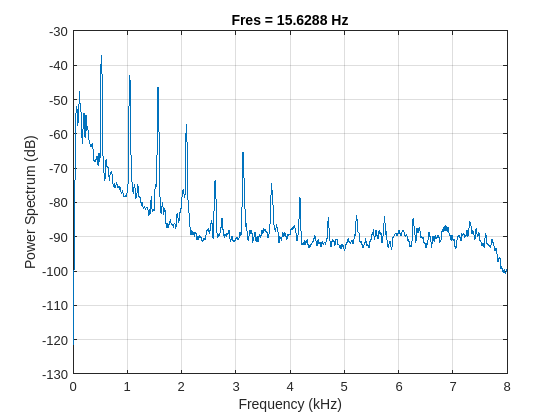

[flute, fs] = audioread("./data/NoisyFlute.wav");
flute = flute(1:7*fs);
pspectrum(flute, fs)

## Task 1

In this activity, you'll generate a simple watermark for the flute recording. You will add the watermark signal with the audio signal, so signals need to have the same length. To ensure both signals have the same length, you can create a time vector for the flute recording. Start by creating a vector of sample indices:

`0``:``n``-1`

where `n` is the length of the signal. You can use the `numel` function to find the number of elements.

The colon (`:`) operator creates an equally spaced row vector. Signals are conventionally stored in MATLAB as column vectors, so you can can transpose the result with the transpose operator (`'`).

n = numel(flute)

n = 112000

t = (0:n-1)'

t =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


## Task 2

To convert from the sample index to the time value in seconds, you can use `t/fs`.

t = t/fs

t =          0
    0.0001
    0.0001
    0.0002
    0.0003
    0.0003
    0.0004
    0.0004
    0.0005
    0.0006


## Task 3

The power above about 5 kHz is around -90 dB, which means that the frequency content is not audible. Any location above 5 kHz would work for the watermark, so you can try inserting a single tone at 6000 Hz.

f = 6000;
wm = sin(2*pi*f*t)

wm =          0
    0.7071
   -1.0000
    0.7071
    0.0000
   -0.7071
    1.0000
   -0.7071
   -0.0000
    0.7071


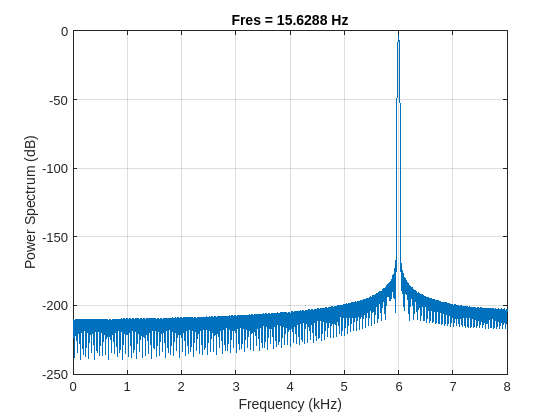

pspectrum(wm, fs)

## Task 4

Now you can combine the audio with the watermark.

marked = wm + flute

marked =          0
    0.7071
   -1.0000
    0.7071
    0.0000
   -0.7071
    1.0000
   -0.7071
   -0.0000
    0.7071


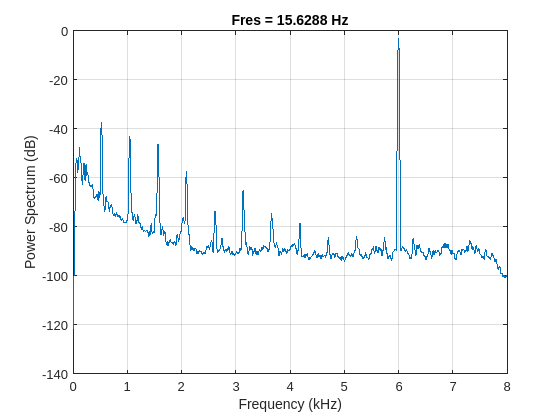

pspectrum(marked, fs)